#### Workspace Plotting

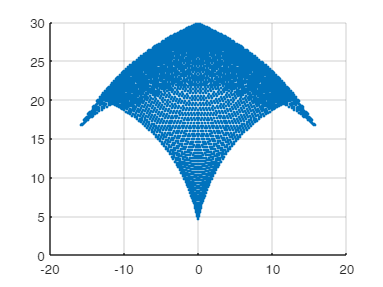

% Define discrete angles
q1 = linspace(0,180,90)*pi/180;
q2 = linspace(0,180,90)*pi/180;

nq1 = length(q1);
nq2 = length(q2);
M = [];
% Calculate end-effector positions
for i=1:nq1
    for j=1:nq2
        M = [M; [q1(i), q2(j)]];
        [x(i,j), y(i,j)] = forwardKinematics(q1(i), q2(j));
    end
end

% Convert units from meter to centimeter
X = 100.*x(:);
Y = 100.*y(:);

scatter(X,Y,'.')
set(gca,"XGrid","on","YGrid","on")

#### Get Boundary Region

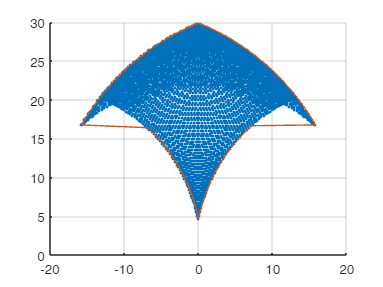

k = boundary(X, Y);
hold on;
plot(X(k), Y(k), '-')

#### Check for random points inside of workspace

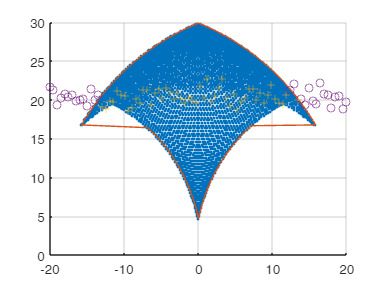

% Generate random points
xq = linspace(-20,20,80);
yq = randn(80,1) + 20;

% Check if inside or on edge of the polygon
[in,on] = inpolygon(xq,yq,X(k), Y(k));
plot(xq(in),yq(in), '+')
plot(xq(~in),yq(~in), 'o')

#### Generate table of angles and positions

M = M.*180./pi;
X = X./100;
Y = Y./100;
M = [M X Y]

M =          0         0    0.1000    0.1875
         0    2.0225    0.1028    0.1893
         0    4.0449    0.1056    0.1909
         0    6.0674    0.1083    0.1924
         0    8.0899    0.1109    0.1938
         0   10.1124    0.1134    0.1951
         0   12.1348    0.1157    0.1963
         0   14.1573    0.1179    0.1974
         0   16.1798    0.1200    0.1984
         0   18.2022    0.1219    0.1993


writematrix(M,'angles and coordinates.csv') 

B = [X(k) Y(k)]

B =     0.1318    0.2037
    0.1297    0.2063
    0.1296    0.2063
    0.1274    0.2090
    0.1250    0.2116
    0.1229    0.2140
    0.1227    0.2142
    0.1203    0.2169
    0.1178    0.2195
    0.1160    0.2215


writematrix(B,'workspace boundaries.csv') 